% data generation
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
model_params = [0 10];
noise_params = [0 1];
step = 0.25;
max_iterations = 1e2;

batch_sizes = [1 10 100 500];

grid = gen_grid();

cirkel_netwerk = NN_gen([2 5 2],'normal',model_params,5000);

%TODO: andere 2 networks

%Cirkel

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Cirkel");
cirkel_data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

th = 0:pi/50:2*pi;
xunit = 0.4 * cos(th) + 0.5;
yunit = 0.4 * sin(th) + 0.5;

for j = 1:4
    trained_net = train_net(cirkel_netwerk, cirkel_data, step, max_iterations, batch_sizes(j), model_params, noise_params);
    
    figure
    corClass = correct_classify_circle(grid);
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_net);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'filled')
    scatter(XB,YB,'filled')
    plot(xunit, yunit); 
    percentage_correct = (cor_counter/length(grid)) * 100

end

% Driehoek

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Driehoek");
driehoek_data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

for j = 1:4
    trained_net = train_net(cirkel_netwerk, driehoek_data, step, max_iterations, batch_sizes(j), model_params, noise_params);
    
    figure
    corClass = correct_classify_circle(grid);
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_net);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == "A"
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == "B"
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    th = 0:pi/50:2*pi;
    xunit = 0.4 * cos(th) + 0.5;
    yunit = 0.4 * sin(th) + 0.5;
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'filled')
    scatter(XB,YB,'filled')
    plot(xunit, yunit); 
    percentage_correct = (cor_counter/length(grid)) * 100

end

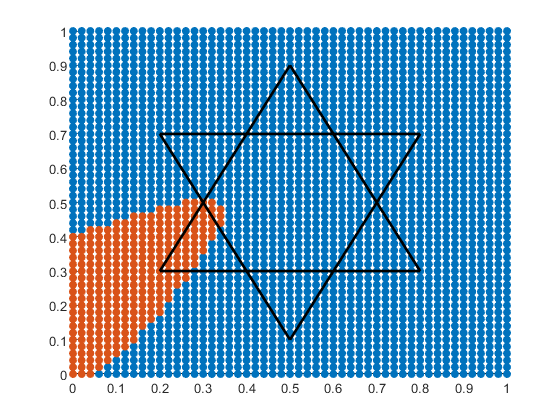

percentage_correct =   31.334102268358322


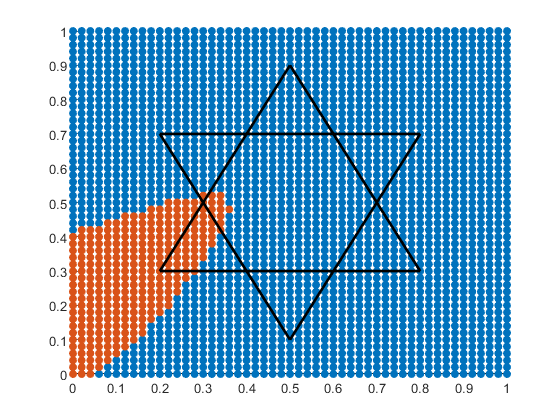

percentage_correct =   31.334102268358322


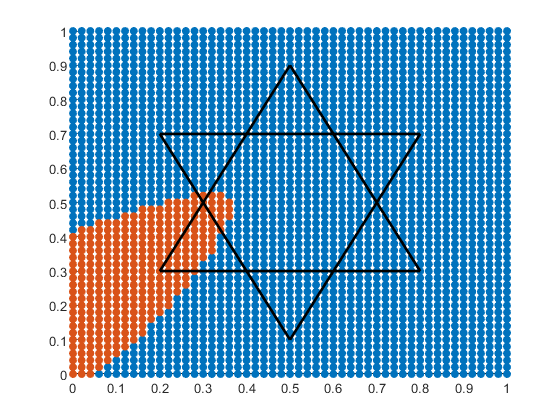

percentage_correct =   31.372549019607842


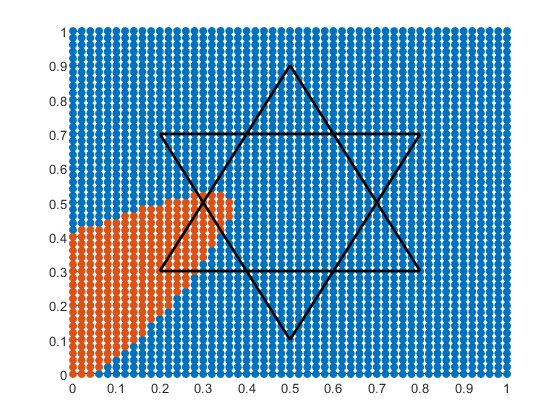

percentage_correct =   31.372549019607842


% Ster

[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,100, "Ster");
ster_data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];

for j = 1:4
    trained_net = train_net(cirkel_netwerk, ster_data, step, max_iterations, batch_sizes(j), model_params, noise_params);
    
    figure
    corClass = correct_classify_star(grid);
    
    XA = {};
    YA = {};
    XB = {};
    YB = {};
    cor_counter = 0;
    for i = 1: length(grid)
        x = [grid(1,i); grid(2,i)];
        a = classify(x, trained_net);
        if a(1) >= a(2)
            XA = [XA, grid(1,i)];
            YA = [YA, grid(2,i)];
            if corClass{i} == 'A'
                cor_counter = cor_counter + 1;
            end
        else
            XB = [XB, grid(1,i)];
            YB = [YB, grid(2,i)];
            if corClass{i} == 'B'
                cor_counter = cor_counter + 1;
            end
        end
    end
    
    XA = cell2mat(XA);
    YA = cell2mat(YA);
    XB = cell2mat(XB);
    YB = cell2mat(YB);
    
    
    
    figure
    hold on
    axis([0 1 0 1])
    scatter(XA,YA,'filled')
    scatter(XB,YB,'filled')
    
    x_tot = linspace (0.2,0.8);
    x1 = linspace (0.2,0.5);
    x2 = linspace (0.5,0.8);
    y1 = (0*x_tot) + 0.7;
    y2 = -2*x1 + 1.1;
    y3 = 2*x2 - 0.9;
    y4 = (0*x_tot) + 0.3;
    y5 = 2*x1 - 0.1;
    y6 = -2*x2 + 1.9;
    plot(x_tot,y1,'black','LineWidth',2);
    plot(x1,y2,'black','LineWidth',2);
    plot(x2,y3,'black','LineWidth',2);
    plot(x_tot,y4,'black','LineWidth',2);
    plot(x1,y5,'black','LineWidth',2);
    plot(x2,y6,'black','LineWidth',2);
     
    percentage_correct = (cor_counter/length(grid)) * 100

end